This is a quick tutorial showing how to use the outline of Amery Ice Shelf as region of interest to get Sentinel 1 ice velocity data from HyP3. 

Written by Chad Greene, September 2020.

## Get the geographic boundaries of Amery Ice Shelf:

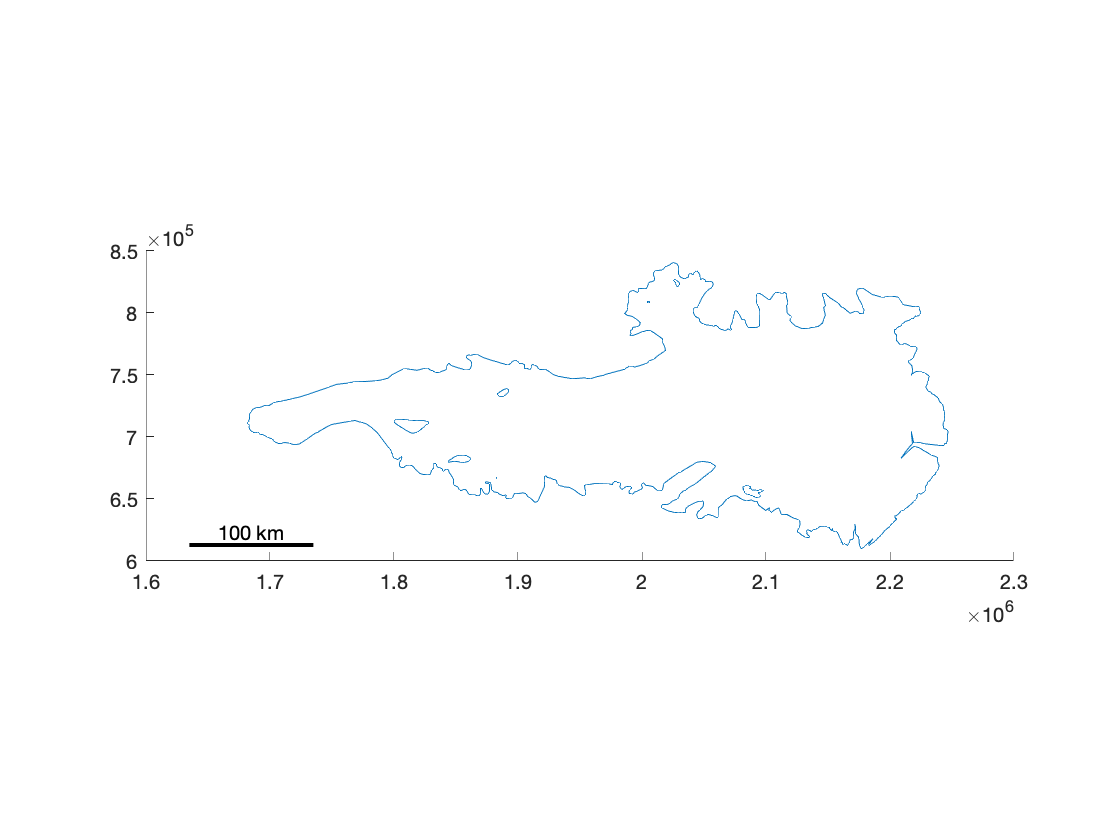

[lat,lon] = antbounds_data('amery'); 

figure
plotps(lat,lon)
scalebarps

## Convert to polar stereographic:

[x,y] = ll2ps(lat,lon);

## Buffer the outline:

The easiest way to do this is with polyshape objects. 

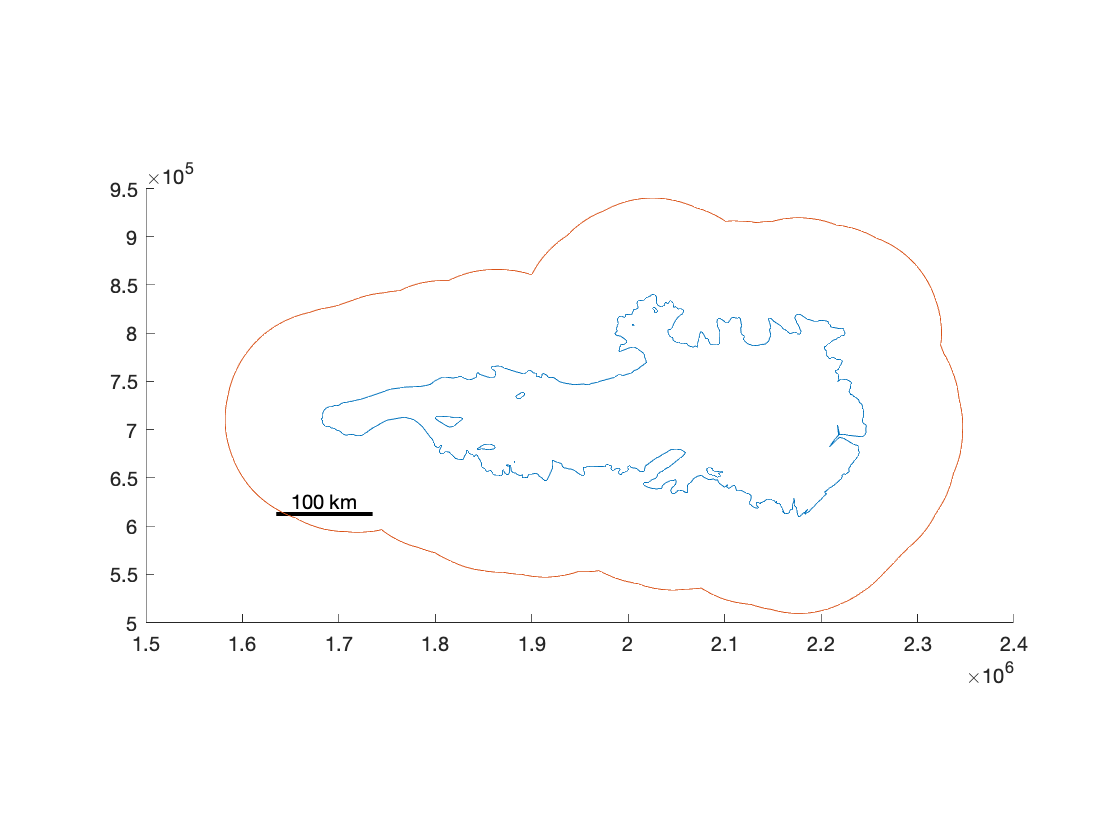

% First, turn the x,y outline into a polyshape object: 
P = polyshape(x,y); 

% Now buffer the outline by 100 km: 
Pb = polybuffer(P,100e3); 

% Get the buffered polyshape outline: 
[xb,yb] = boundary(Pb);

% Plot the buffered ice shelf outline: 
hold on
plot(xb,yb)

## Write a well-known text file

This is a specific file format that can be understood by HyP3. The ps2wkt function accepts input coordinates as lat,lon or x,y. Here we'll just give it the buffered xb,yb arrays we created, and we'll make a file called amery.wkt: 

ps2wkt(xb,yb,'amery.wkt')

% Now go drop amery.wkt into the HyP3 subscription service thingy.